# 01 Hands On Discrete Systems - 1D spring system - Part 2

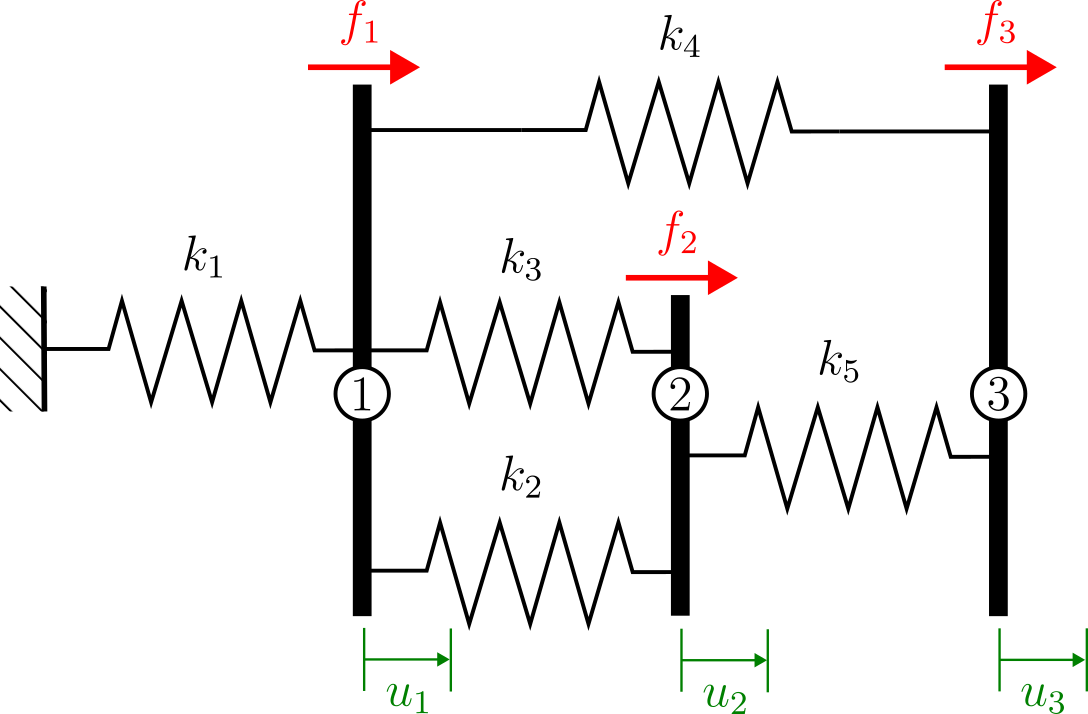

**Given quantities:**

- 
$$k_1=~20 ~\frac{\text{N}}{\text{m}}, \quad k_2=k_3=k_4=10~\frac{\text{N}}{\text{m}}, \quad k_5 = 15~\frac{\text{N}}{\text{m}}$$


- 
$$f_1 = 0.5~\text{N}, \quad f_2 = 1~\text{N},\quad f_3=1.2~\text{N}$$


clear all; clc; close all;

% Given quantities
k1 = 20;    % [N/m]
k2 = 10;    % [N/m]
k3 = 10;    % [N/m]
k4 = 10;    % [N/m]
k5 = 15;    % [N/m]

f1 = 0.5;   % [N]
f2 = 1;     % [N]
f3 = 1.2;   % [N]

The system of equations for a single spring is given by


$$k\left\lbrack \begin{array}{cc}
1 & -1\\
-1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_i \\
u_{i+1} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
f_i \\
f_{i+1} 
\end{array}\right\rbrack$$


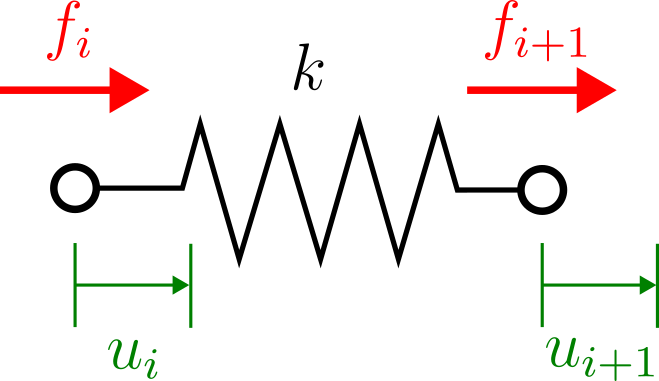

In order to assemble the global stiffness matrix, we construct the connectivity matrix. As MATLAB array indices start from 0, we shift all indices by 1.

% Connectivity matrix
connectivity = [1, 2;
           2, 3;
           2, 3;
           2, 4;
           3, 4];

Using the given spring stiffnesses and the connectivity matrix, we can efficiently assemble the global stiffness matrix by looping over the connectivity matrix in order to add the local stiffness terms to the global matrix.

% Initialize global stiffness matrix
K = zeros(4,4);

% General element stiffness matrix
K0 = [1, -1;
      -1, 1];

ke = [k1, k2, k3, k4, k5]

ke =     20    10    10    10    15


% Loop over spring elements
for spring = 1:5
    % Get element connectivity
    edof = connectivity(spring, :);

    % Compute element stiffness matrix
    Ke = ke(spring) * K0;

    % Add to global stiffness matrix
    K(edof, edof) = K(edof, edof) + Ke;
end
K

K =     20   -20     0     0
   -20    50   -20   -10
     0   -20    35   -15
     0   -10   -15    25


% Force vector
f = [f1; f2; f3]

f =     0.5000
    1.0000
    1.2000


% Solution of the system
u = K(2 : end, 2 : end) \ f

u =     0.1350
    0.2012
    0.2227


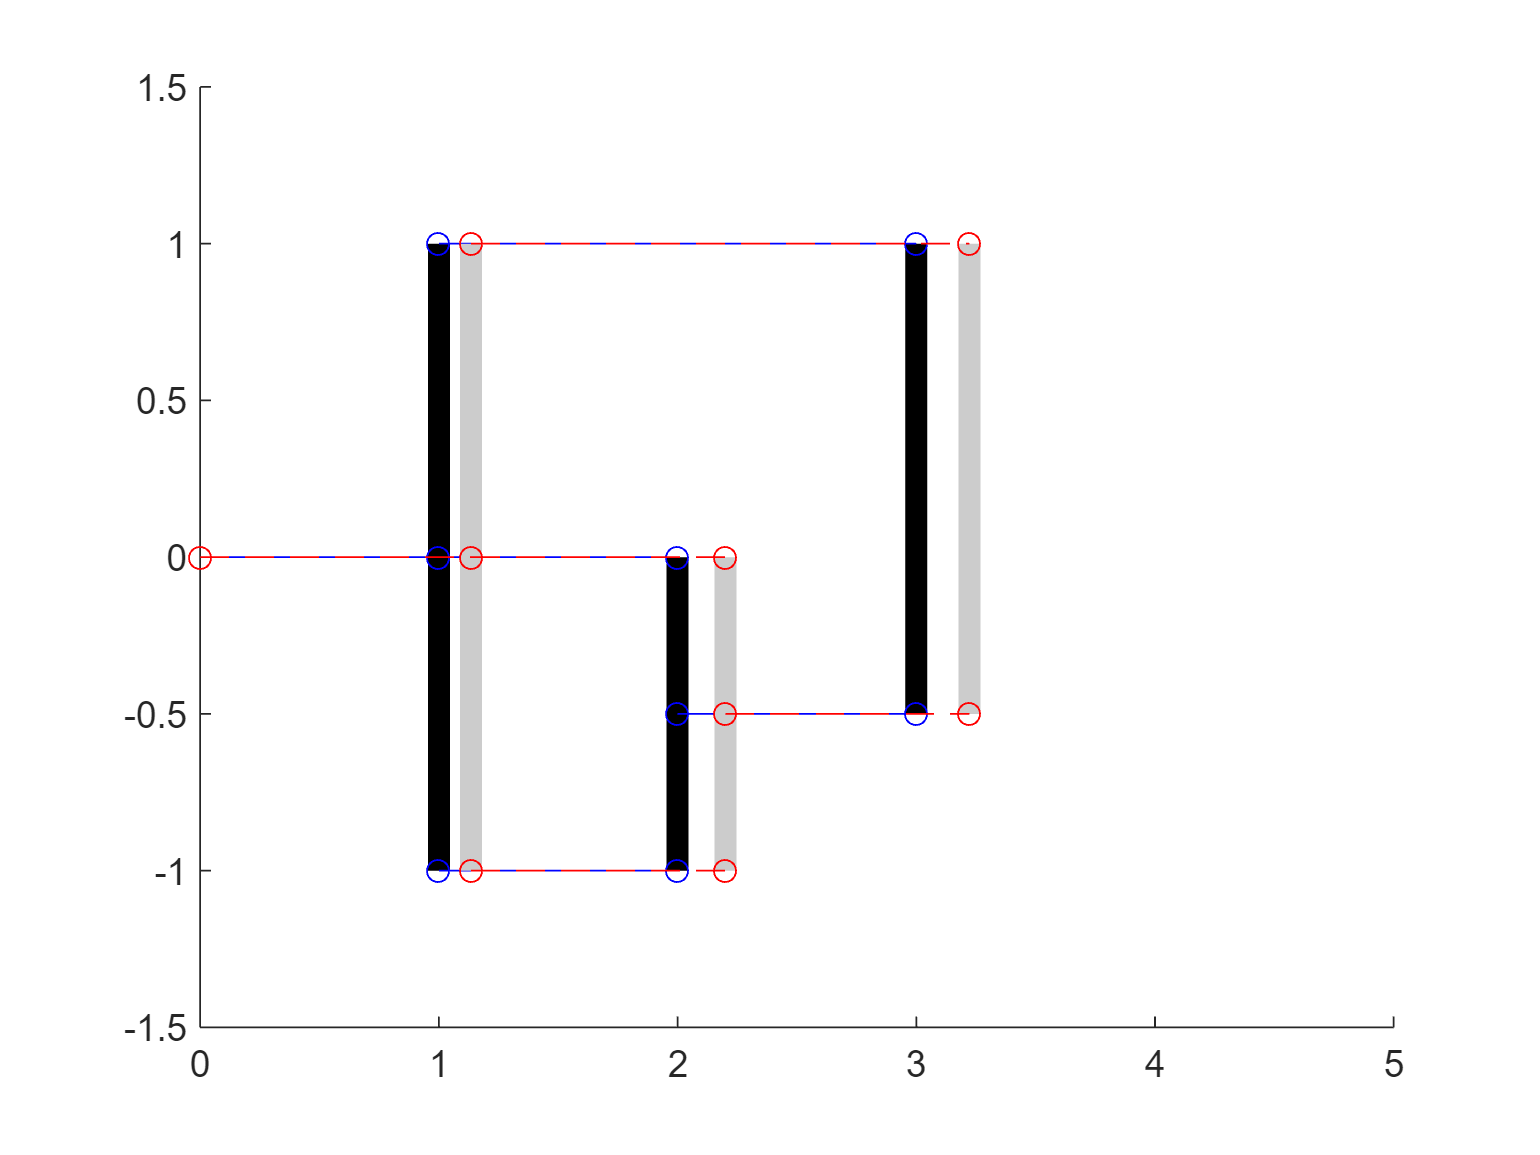

% Add fixed degree of freedom to displacement vector
u = [0; u];

% Set up nodal coordinates
x0 = transpose(0:3);

% Visualize results
plotSystem(x0);
xlim([0, 5]);
ylim([-1.5, 1.5]);
plotSystem(x0 + u, 'r');

Having solved the system, we can easily compute the force at the boundary $f_0$. Recall the full system of equations after inserting the solution for the displacements:


$$\left\lbrack \begin{array}{cccc}
20 & -20 & 0 & 0\\
-20 & 50 & -20 & -10\\
0 & -20 & 35 & 0\\
0 & -10 & 0 & 10
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
0\ldotp 135\\
0\ldotp 2012\\
0\ldotp 2227
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
f_0 \\
0\ldotp 5\\
1\\
1\ldotp 2
\end{array}\right\rbrack$$


f0 = K(1,:) * u

f0 = -2.7000

function plotSystem(x, colorSpring)
    % Plot assemblage of springs for problem 1.2
    % INPUT:
    %   x (array)               Nodal positions, x-coordinates.
    %   color (string/array)    OPTIONAL Color for spring in plot.
    if nargin == 1 
            colorSpring = 'b';
            colorNode = 'k';
            lineStyle = '-o';
    elseif nargin == 2
            colorNode = [0.8, 0.8, 0.8];
            lineStyle = '--o';
    else
            error("Unknown number of arguments.");                  
    end
    
    x1 = [x(1); x(2)];
    x2 = [x(2); x(3)];
    x3 = x2;
    x4 = [x(2); x(4)];
    x5 = [x(3); x(4)];
    y1 = [0; 0];
    y2 = [-1; -1];
    y3 = y1;
    y4 = [1; 1];
    y5 = [-0.5; -0.5];
    
    hold on;
    % Plot bars/nodes
    plot([x1(2), x2(2), x5(2); x1(2), x3(2), x4(2)], [y2(1), y2(1), y5(1); y4(1), y3(1), y4(1)], '-', Color = colorNode, LineWidth = 6)
    
    % Plot springs as lines
    plot([x1, x2, x3, x4, x5], [y1, y2, y3, y4, y5], lineStyle, Color = colorSpring)
    hold off;
end